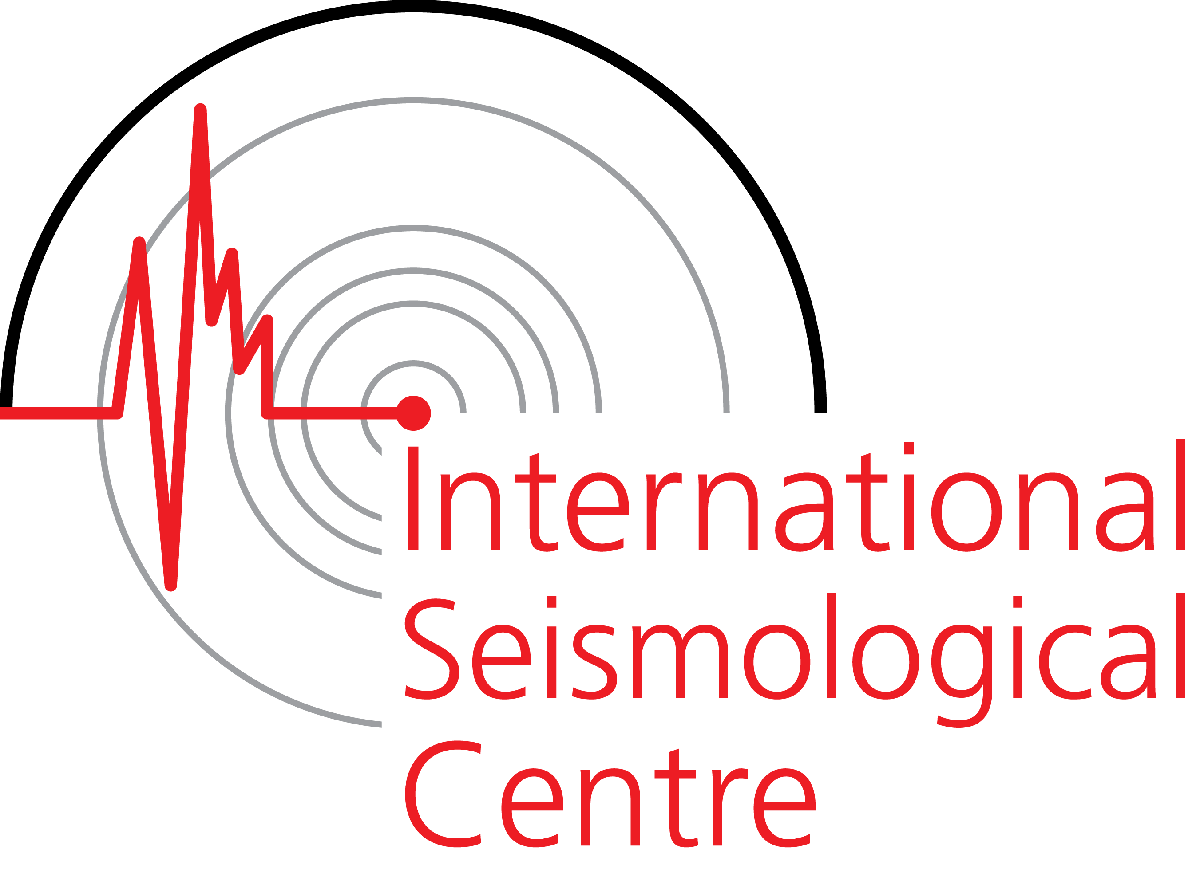

# The ISC Earthquake Toolbox for MATLAB

Earthquakes are monitored by many agencies across  the world, with  each agency considering  a different set of seismic stations and concentrating on earthquakes that occur in different countries  or regions. Through well-established data sharing pathways, much of this data is made available to the International Seismological Centre (ISC). We combine these earthquake observations to produce  a global earthquake catalogue that is as definitive as possible using data from over 100 agencies, in over 40 different countries. These earthquake locations are then made freely available, along with all other earthquake  observations that are shared with us in the ISC Bulletin.

Together with collaborators at MathWorks, the ISC has developed a ISC Earthquake Toolbox for MATLAB in order to provide efficient access to this data, allowing the data to be easily manipulated data from this huge resource of earthquake observations to be easily used and manipulated in the MATLAB environment.

In this Tutorial we will demonstrate how to;

- Download ISC data from using the interactive MATLAB GUI

- Plot Earthquake Locations from a test data set

- Compare earthquake magnitude types, and estimate the magnitude of  completeness

setupISCtoolbox; % Adds the path and sets the enviroment for the ISC Earthquake Toolbox for MATLAB

## Step 1: Downloading ISC Data

The ISC database can be directly queried using the MATLAB livescript called '*ISCtoolbox_WB1_Download_ISC_Data.mlx*', which is distributed  with the ISC earthquake toolbox. The GUI has many of the same options as the conventional ISC web search, but has the advantage that the data is downloaded and saved directly in MATLAB data tables. The screenshot below shows a flavour off the options available during the download. You can build a data set for a given time period, a set range of earthquake magnitudes and for a specific area by interactively defining a search polygon. For more details see the livescript '*ISCtoolbox_WB1_Download_ISC_Data.mlx*'.

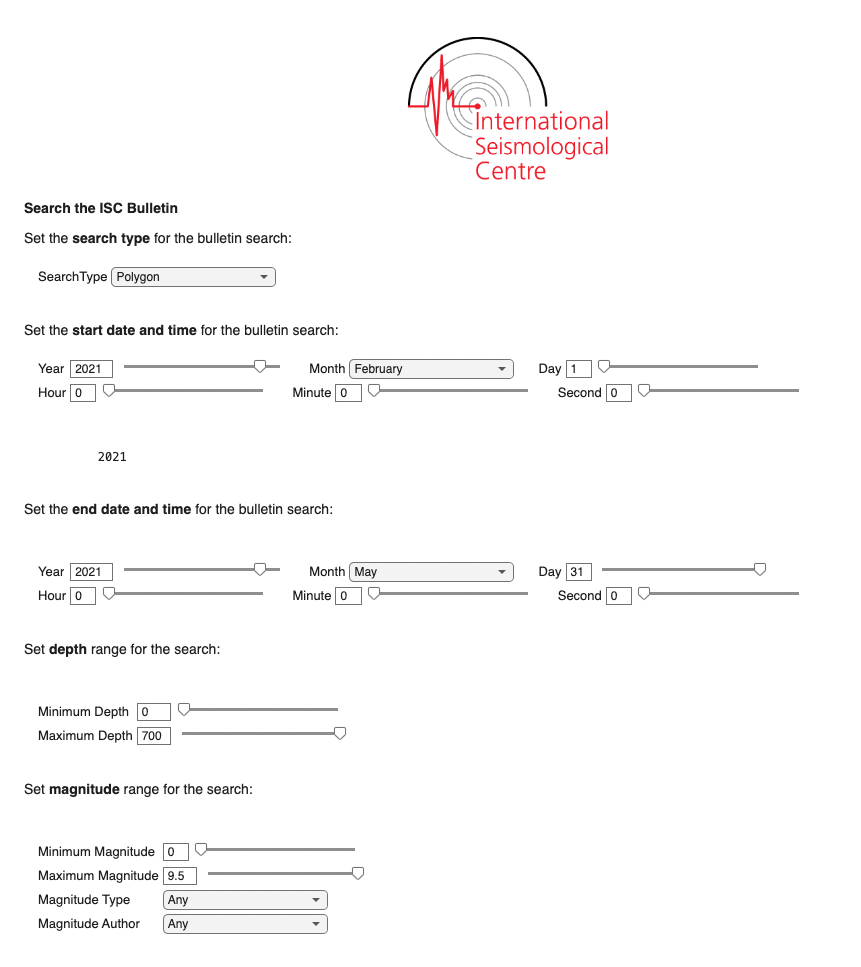

## Step 2: Plotting Earthquake Locations

In this tutorial we will use a pre-downloaded data set created with the ISC Earthquake Toolbox for MATLAB download tool. 

load('Data/Downloaded_ISC_Data/Alaska_2000_2020_mw4_0plus.mat');

### Extract and Plot Earthquake Locations from the data set

Here we get the earthquake latitude, longitude, depth and origin time from the data table called 'allPrimes'. Other information here includes the author of the earthquake locations (ISC) in this case and information about the uncertainty in the earthquake location (i.e. the error ellipse).

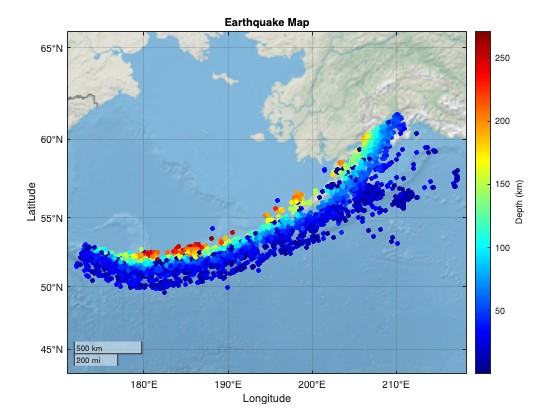

% Read earthquake location parameters from data tables
eq_lats = allPrimes.Latitude;
eq_lons = allPrimes.Longitude;
eq_depths = allPrimes.Depth;
eq_times = allPrimes.Date;

% Convert negative longtidudes to range 0-360 to allow plotting 
% in MATLAB
for n = 1:numel(eq_lons)
    if eq_lons(n) < 0
        eq_lons(n) = eq_lons(n) + 360;
    end
end

% Plot the data in 3D
geobasemap landcover;
geoscatter(eq_lats, eq_lons, 25, eq_depths, 'filled');
colormap jet;
c = colorbar;
c.Label.String = 'Depth (km)';
title('Earthquake Map');

### Plot the earthquake depths in 3D

The distribution of earthquakes can tell us a lot about the structure of fault zones and particularly subduction zones. In the images below seismicity in the Alaska-Aleutian arc in the North pacific is plotted in 3D.

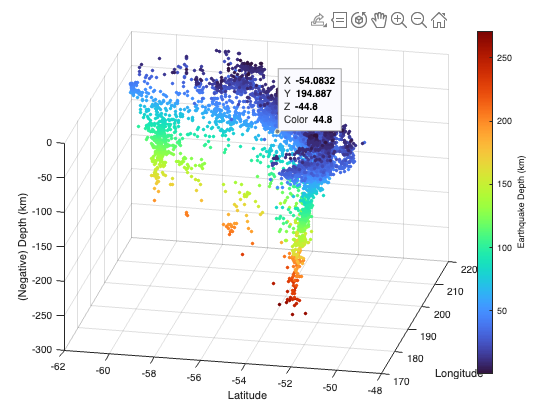

% Here we create a 3D scatter plot, showing earthquake depth distributions.
figure
scatter3(eq_lats*-1, eq_lons, eq_depths*-1, 100, eq_depths, '.')
colormap turbo; 
c = colorbar;
c.Label.String = 'Earthquake Depth (km)';

xlabel('Latitude');
ylabel('Longitude');
zlabel('(Negative) Depth (km)');
view([12 29])

## Step 3: Magnitude Comparisons

As well as including a wide range of seismic phase arrival times and earthquake locations from many different earthquake monitoring agencies, the ISC also curates and caluclutes several different magnitude types. A more detailed exploration of these magnitude types is given in the livescript titled '*ISCtoolbox_WB3_Exploring_Earthquake_Magnitudes.mlx*'. Here we compare the ISC bod wave magnitide (mb) to the moment magnitude (Mw) reported by gCMT.

% Get local copy of the event IDs for the data set
prime_evids = allPrimes.EventID;

% For each of the EVIDs get the ISC mb and gCMT Mw, populating the rray with NaNs if either are not present
for n = 1:size(prime_evids, 1)

    % Get evid for given event
    evid = prime_evids(n);
    evid_idx = allMagnitudes.EventID == evid;
    
    % Get magnitudes for that event
    event_mags = allMagnitudes(evid_idx,:);

    % Get ISC mb for that event, set to NaN if not available
    idx = event_mags.MagnitudeType == 'mb';
    event_mags = event_mags(idx,:);
    idx = event_mags.Author == 'ISC';
    event_mags = event_mags(idx,:);

    if size(event_mags,1) == 1
        isc_mbs(n) = event_mags.Magnitude;
    else
        isc_mbs(n) = NaN;
    end

    % Get GCMT Mw for that event, set to NaN if not available
    event_mags = allMagnitudes(evid_idx,:);
    idx = event_mags.MagnitudeType == 'MW';
    event_mags = event_mags(idx,:);
    idx = event_mags.Author == 'GCMT';
    event_mags = event_mags(idx,:);

    if size(event_mags,1) == 1
        gcmt_mws(n) = event_mags.Magnitude;
    else
        gcmt_mws(n) = NaN;
    end
end

### Plot ISC mb magnitudes vs gCMT Mw

We compare the boday wave magnitude (mb) from the ISC with the moment magnitude (Mw) of the gCMT for the area considered. Different magnitude types have different advantages, with mb being calculated to much lower magnitudes that Mw, whjile Mw is usefull as it can directly be related to the energy released in an earthquake.

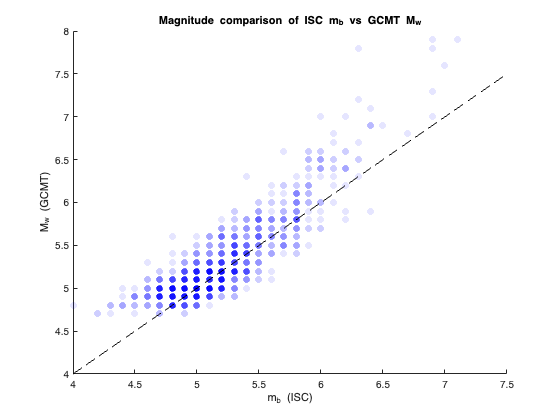

figure; hold on;
scatter(isc_mbs, gcmt_mws, 'MarkerFaceColor','b','MarkerEdgeColor','b',...
    'MarkerFaceAlpha',0.1,'MarkerEdgeAlpha',0.1);
xs = linspace(4.0, 7.5, 10); ys = xs;
plot(xs, ys, 'k--');

title('Magnitude comparison of ISC m_b vs GCMT M_w');
xlabel('m_b (ISC)');
ylabel('M_w (GCMT)');

## Calculte magnitude of completeness and b-value for ISC mb and gCMT Mw

The ISC Eartthquake Toolbox MATLAB also supports a simple Gutenberg-Richter anaylsis, calcuating the b-valuie and magnitude of completeness. Below we compare the Gutenberg-Richter plots for this are using both the GCMT Mw magtiudes and the ISC mb magnitudes. The plot shows that the mb values are relatively deffiecient in higher magnitudes, likely due to the satration mb at higher magnitudes. The magnitude of completeness is though lower for mb, with many more magnitudes of lower value reported.

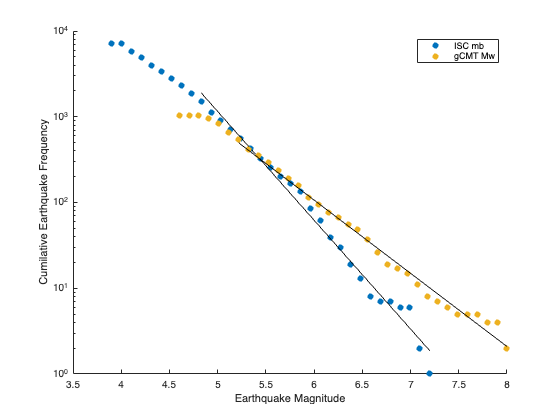

figure; hold on;
Mc_manual = 0;     % Set to zero for undefined
Mmax_manual = 0;   % This is the maximum magntiude that b-value calculation 
                   % fits. Set ot zero for undefined
plot_mc_b_fig = 1; % Select whether to plot the b-value fit (1=yes, 0=no)
plot_text     = 0; % Select whether output b-value and Mc values as text on figure (1=yes, 0=no)
[a_mb,b_mb] = estimate_mc_b(isc_mbs, Mc_manual, Mmax_manual, plot_mc_b_fig, plot_text);

Mc_manual = 0;     % Set to zero for undefined
Mmax_manual = 0;   % This is the maximum magntiude that b-value calculation 
                   % fits. Set ot zero for undefined
[a, b, mag_distr, x_mags, h_mag, ab_fit] = estimate_mc_b(gcmt_mws, Mc_manual, ...
    Mmax_manual, plot_mc_b_fig, plot_text);
legend('ISC mb', '', 'gCMT Mw', '');